# PGD Approximation of a random space-time field 

# - A POSTERIORI-

*V. Matray*

clear all
close all
clc

Time discretisation

T   = 10; 
n_T = 400; 
tf  = linspace(0,T,n_T);     % fine discretisation
tc  = linspace(0,T,n_T/10);  % coarse discretisation
dt  = tf(2); % time step

Space discretisation

L = 1; 
n_X = 200; 
xf  = linspace(0,T,n_X);    % fine discretisation
xc  = linspace(0,T,n_X/10); % coarse discretisation
dx  = xf(2);

Display of the field smoothed to approximated by PGD 

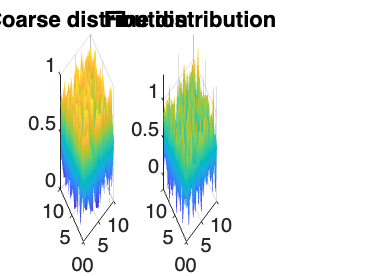

% Meshes (fine and coarse)
[mesh_x_f,mesh_t_f] = meshgrid(xf,tf);
[mesh_x_g,mesh_t_g] = meshgrid(xc,tc);

% Random function on the coarse mesh:
Ug = rand(n_T/10,n_X/10);

% Interpolation on the fine mesh to get a 
% smooth distribution : (If the field is too discontinuous
% the PGD will have trouble approximating it: 
% you can check this at the end of the session).

Uf = interp2(mesh_x_g,mesh_t_g,Ug,mesh_x_f,mesh_t_f,'spline');

% Display distribution
figure()
subplot(1,3,1)
surf(xc,tc,Ug)
title("Coarse distribution")
shading interp

subplot(1,3,2)
surf(xf,tf,Uf)
title("Fine distribution")
shading interp

## Elementary matrix and assembly for integration 

%TO DO

## PGD Approximation

% Number of modes
n_modes    = 200;

% initialisation
Lambda     = zeros(n_T,n_modes);
Gamma      = zeros(n_X,n_modes);
U_PGD      = zeros(n_T,n_X);
PGD_error = zeros(n_modes,1);

Greedy algorithm + fixed point 

for mode = 1:n_modes
    
    U_PGD = Lambda*Gamma';
    
    % Add new mode
    
    
    
    
    % Fixed point algorithm
    while 1% ?
        
      
        
        % Save old function Lambda
        
        
        % Compute new space function Gamma
        
        
        % Normalisation

        
        % Compute new space function Lambda

        
        % update PGD error for stagnation criteria
        
    end
    

    % Orthogonalisation
     %We'll do this after we've successfully run the greedy
     % algorithm and managed to calculate the error in 
     % space-time. All we need to do here is to implement 
     % the Gram-Schmidt algorithm.
     % Note that mode orthogonalization is not useful here,
     % but it will be in the next TP 
     % (a priori use of the PGD).

    % compute the new PGD approximation with the added mode
    U_PGD = Lambda*Gamma';
    
    % Calculation of the reconstruction error with the sptio-temporal norm
   
    
    
%     surf(mesh_x_f,mesh_t_f,U_PGD)
%     xlabel('x')
%     ylabel('y')
%     zlabel('U PGD')
%     shading interp
%     Title = ["Approximation with "+ mode " mode(s)"];
%     title(Title)
%     pause
end 
